# PS9

**By Ari Porad**

**Introduction to Sensors, Instrumentation, and Measurement**

## Note

As specified by the assignment instructions, the resistors and capacitors have the following values for all circuits:


$$\begin{array}{l}
R_1 =1k\Omega \\
R_2 =10k\Omega \\
C_1 =1\mu F\;\left({10}^{-6} \;F\right)\\
C_2 =0\ldotp 1\mu F\;\left({10}^{-7} \;F\right)
\end{array}$$


## Circuit 1: RC + OpAmp

syms R1 R2 C1 C2 w

figure(1); clf;
V_1 = (1/(1j * w * C1)) / (R1 + (1/(1j * w * C1)))

$$V\_1 = -\frac{1\,\mathrm{i}}{C_{1}\,w\,\left(R_{1}-\frac{1\,\mathrm{i}}{C_{1}\,w}\right)}$$

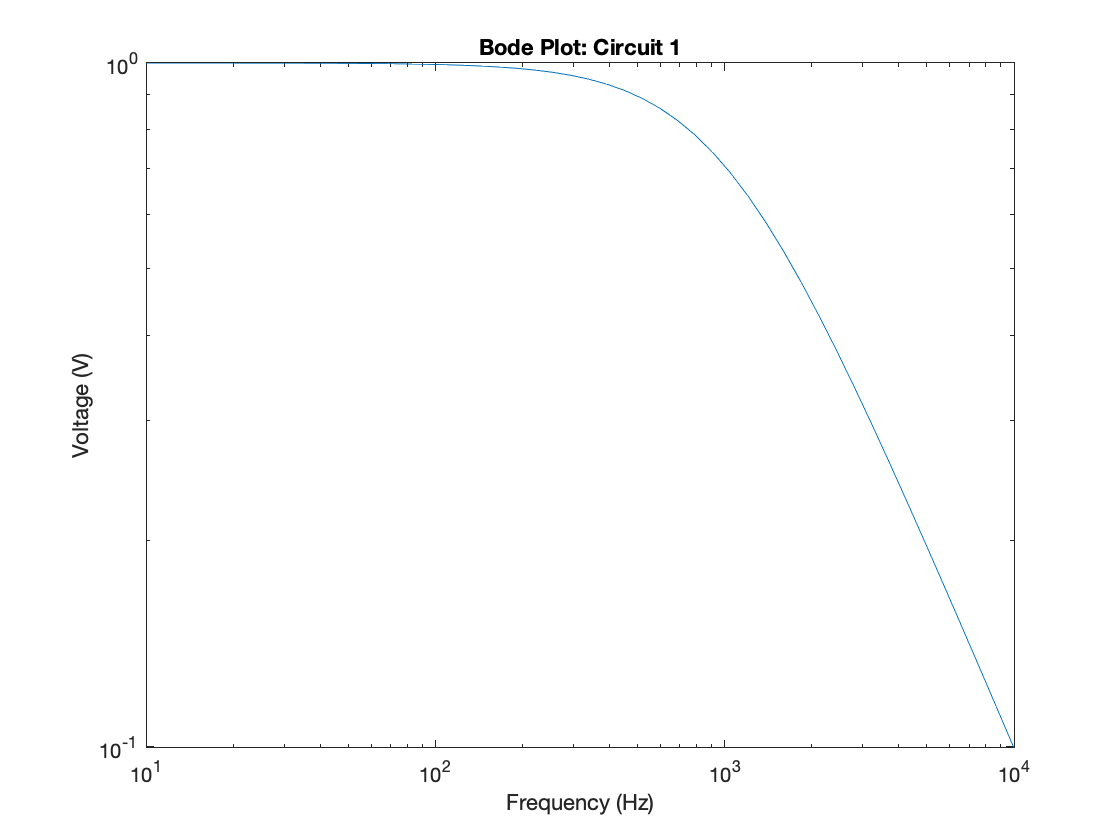

mag = matlabFunction(norm(subs(V_1, [R1, R2, C1, C2], [1000, 10000, 10^-6, 10^-7])));
freq_range = logspace(1, 4);
loglog(freq_range, mag(freq_range));
title("Bode Plot: Circuit 1");
xlabel("Frequency (Hz)");
ylabel("Voltage (V)");

## Circuit 2: R + (R || C) + OpAmp

syms R1 R2 C1 C2 w

figure(2); clf;
V_2 = (1 / ((1/R2) + (1j * w * C2))) / (R1 + (1/((1/R2) + (1j * w * C2))))

$$V\_2 = \frac{1}{\left(\frac{1}{R_{2}}+1\,C_{2}\,w\,\mathrm{i}\right)\,\left(R_{1}+\frac{1}{\frac{1}{R_{2}}+1\,C_{2}\,w\,\mathrm{i}}\right)}$$

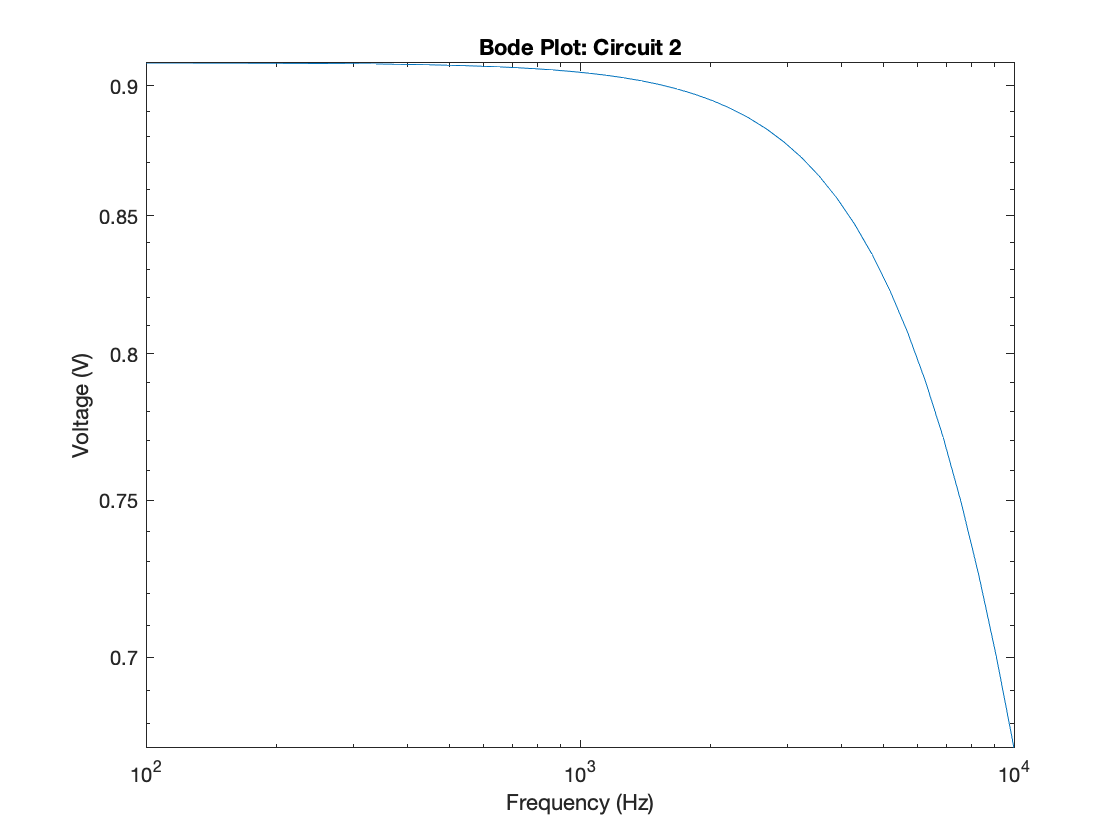

mag = matlabFunction(norm(subs(V_2, [R1, R2, C1, C2], [1000, 10000, 10^-6, 10^-7])));
freq_range = logspace(2, 4);
loglog(freq_range, mag(freq_range));
title("Bode Plot: Circuit 2");
xlabel("Frequency (Hz)");
ylabel("Voltage (V)");

## Circuit 3: CR + OpAmp

syms R1 R2 C1 C2 w

figure(3); clf;
V_3 = (1j * w * R1 * C1) / (1 + (1j * w * R1 * C1))

$$V\_3 = \frac{1\,C_{1}\,R_{1}\,w\,\mathrm{i}}{1+1\,C_{1}\,R_{1}\,w\,\mathrm{i}}$$

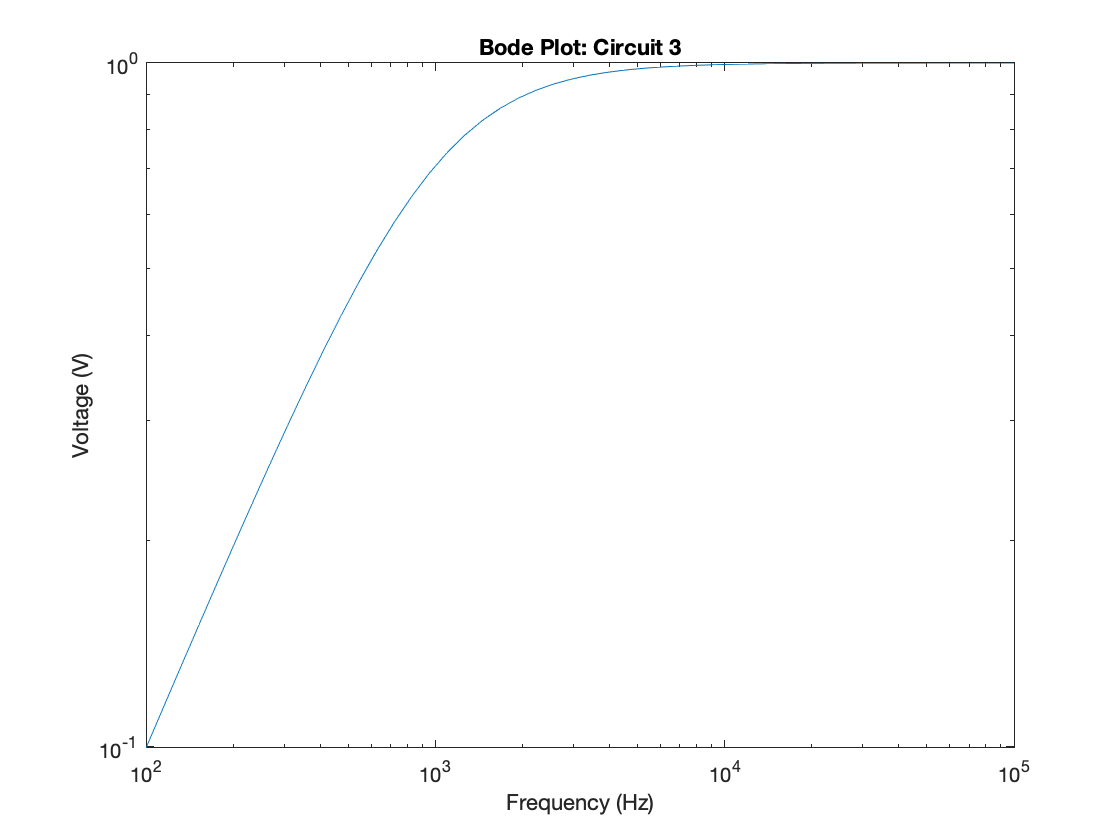

mag = matlabFunction(norm(subs(V_3, [R1, R2, C1, C2], [1000, 10000, 10^-6, 10^-7])));
freq_range = logspace(2, 5);
loglog(freq_range, mag(freq_range));
title("Bode Plot: Circuit 3");
xlabel("Frequency (Hz)");
ylabel("Voltage (V)");

## Circuit 4: R + C + (C || R) + OpAmp

syms R1 R2 C1 C2 w

figure(4); clf;
Z1 = (R1 + (1 / (1j * w * C1)));
Z2 = 1 / ((1 / R2) + (1j * w * C2));
V_4 = Z2 / (Z1 + Z2)

$$V\_4 = \frac{1}{\left(\frac{1}{R_{2}}+1\,C_{2}\,w\,\mathrm{i}\right)\,\left(R_{1}+\frac{1}{\frac{1}{R_{2}}+1\,C_{2}\,w\,\mathrm{i}}-\frac{1\,\mathrm{i}}{C_{1}\,w}\right)}$$

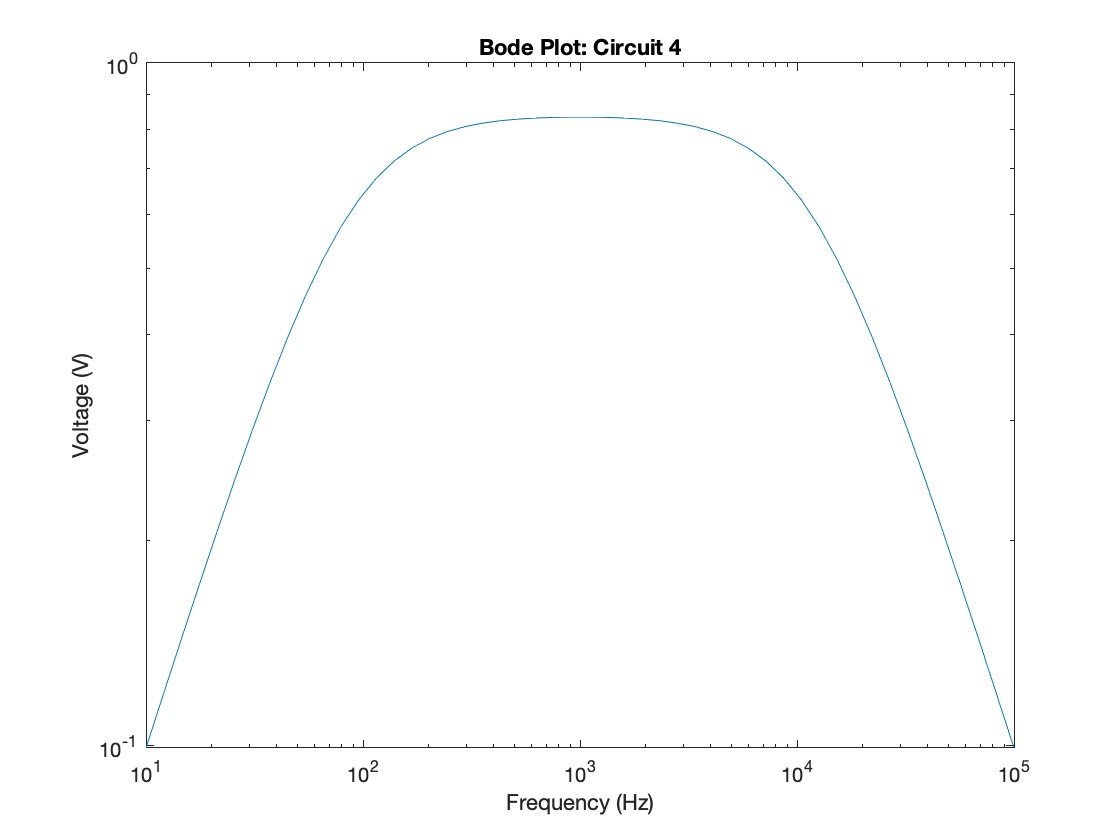

mag = matlabFunction(norm(subs(V_4, [R1, R2, C1, C2], [1000, 10000, 10^-6, 10^-7])));
freq_range = logspace(1, 5);
loglog(freq_range, mag(freq_range));
title("Bode Plot: Circuit 4");
xlabel("Frequency (Hz)");
ylabel("Voltage (V)");

## Circuit 5: RC Voltage Divider

syms R1 R2 C1 C2 w

figure(5); clf;
V_5 = (1 / (1 + (1j * w * R1 * C1)))

$$V\_5 = \frac{1}{1+1\,C_{1}\,R_{1}\,w\,\mathrm{i}}$$

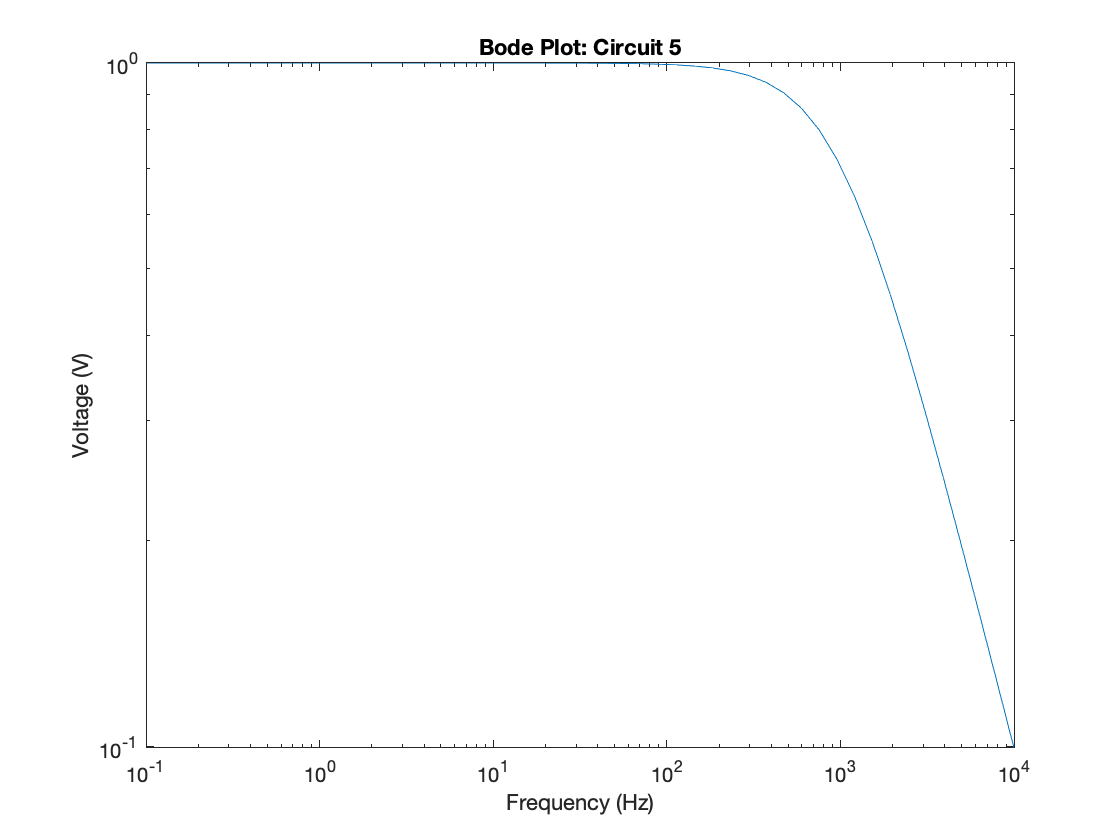

mag = matlabFunction(norm(subs(V_5, [R1, R2, C1, C2], [1000, 10000, 10^-6, 10^-7])));
freq_range = logspace(-1, 4);
loglog(freq_range, mag(freq_range));
title("Bode Plot: Circuit 5");
xlabel("Frequency (Hz)");
ylabel("Voltage (V)");

## Circuit 6: RC + RC

syms R1 R2 C1 C2 w

figure(6); clf;
VaVin = 1 / (1 + (1j * w * R1 * C1));
VoutVa = 1 / (1 + (1j * w * R2 * C2));
V_6 = VoutVa * VaVin

$$V\_6 = \frac{1}{\left(1+1\,C_{1}\,R_{1}\,w\,\mathrm{i}\right)\,\left(1+1\,C_{2}\,R_{2}\,w\,\mathrm{i}\right)}$$

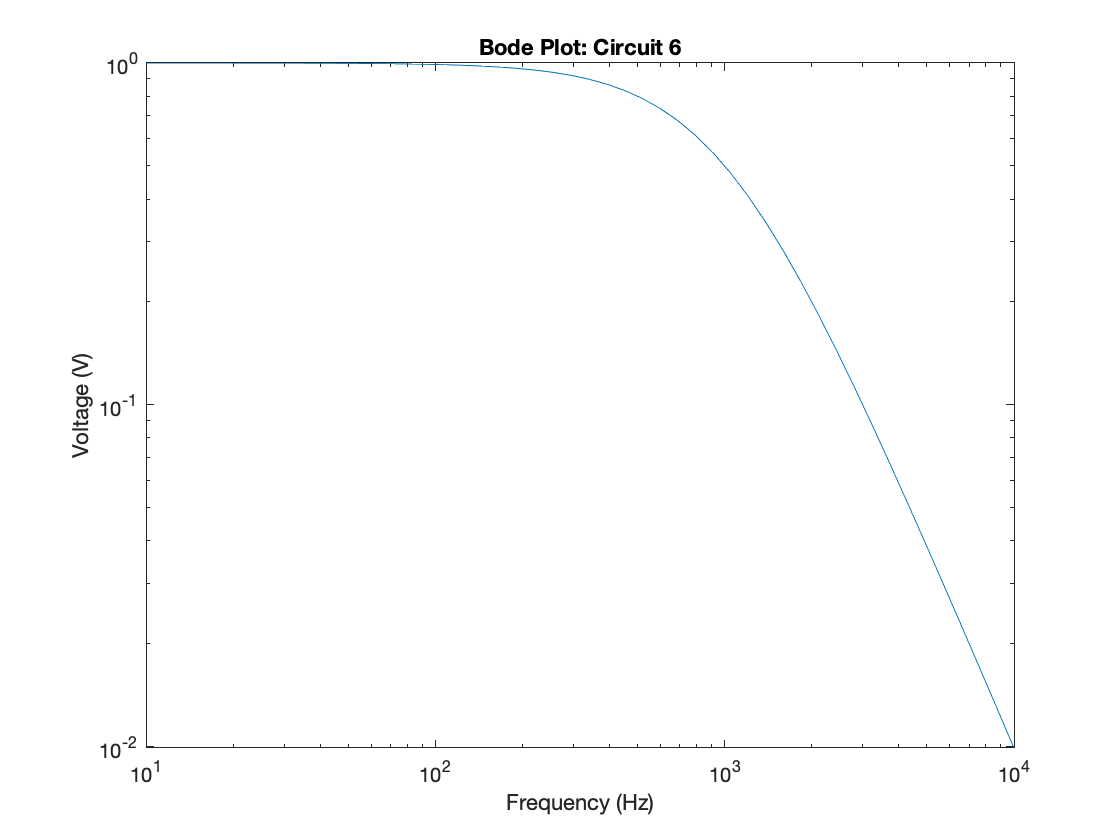

mag = matlabFunction(norm(subs(V_6, [R1, R2, C1, C2], [1000, 10000, 10^-6, 10^-7])));
freq_range = logspace(1, 4);
loglog(freq_range, mag(freq_range));
title("Bode Plot: Circuit 6");
xlabel("Frequency (Hz)");
ylabel("Voltage (V)");

## Circuit 7: RC + RC but reversed

syms R1 R2 C1 C2 w

figure(7); clf;
VaVin = 1 / (1 + (1j * w * R2 * C2));
VoutVa = 1 / (1 + (1j * w * R1 * C1));
V_7 = VoutVa * VaVin

$$V\_7 = \frac{1}{\left(1+1\,C_{1}\,R_{1}\,w\,\mathrm{i}\right)\,\left(1+1\,C_{2}\,R_{2}\,w\,\mathrm{i}\right)}$$

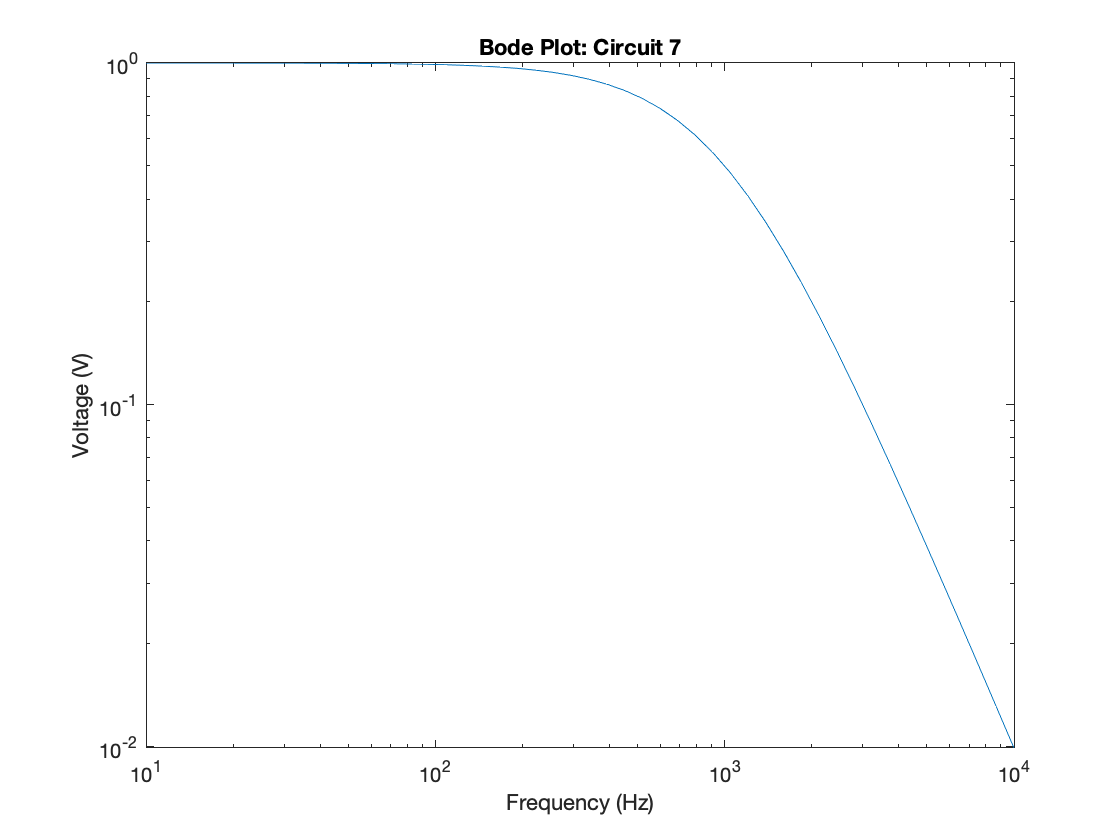

mag = matlabFunction(norm(subs(V_7, [R1, R2, C1, C2], [1000, 10000, 10^-6, 10^-7])));
freq_range = logspace(1, 4);
loglog(freq_range, mag(freq_range));
title("Bode Plot: Circuit 7");
xlabel("Frequency (Hz)");
ylabel("Voltage (V)");

## Circuit 8: RC + CR

syms R1 R2 C1 C2 w

figure(8); clf;
VaVin = 1 / (1 + (1j * w * R2 * C2));
VoutVa = (1j * w * R1 * C1) / (1 + (1j * w * R1 * C1));
V_8 = VoutVa * VaVin

$$V\_8 = \frac{1\,C_{1}\,R_{1}\,w\,\mathrm{i}}{\left(1+1\,C_{1}\,R_{1}\,w\,\mathrm{i}\right)\,\left(1+1\,C_{2}\,R_{2}\,w\,\mathrm{i}\right)}$$

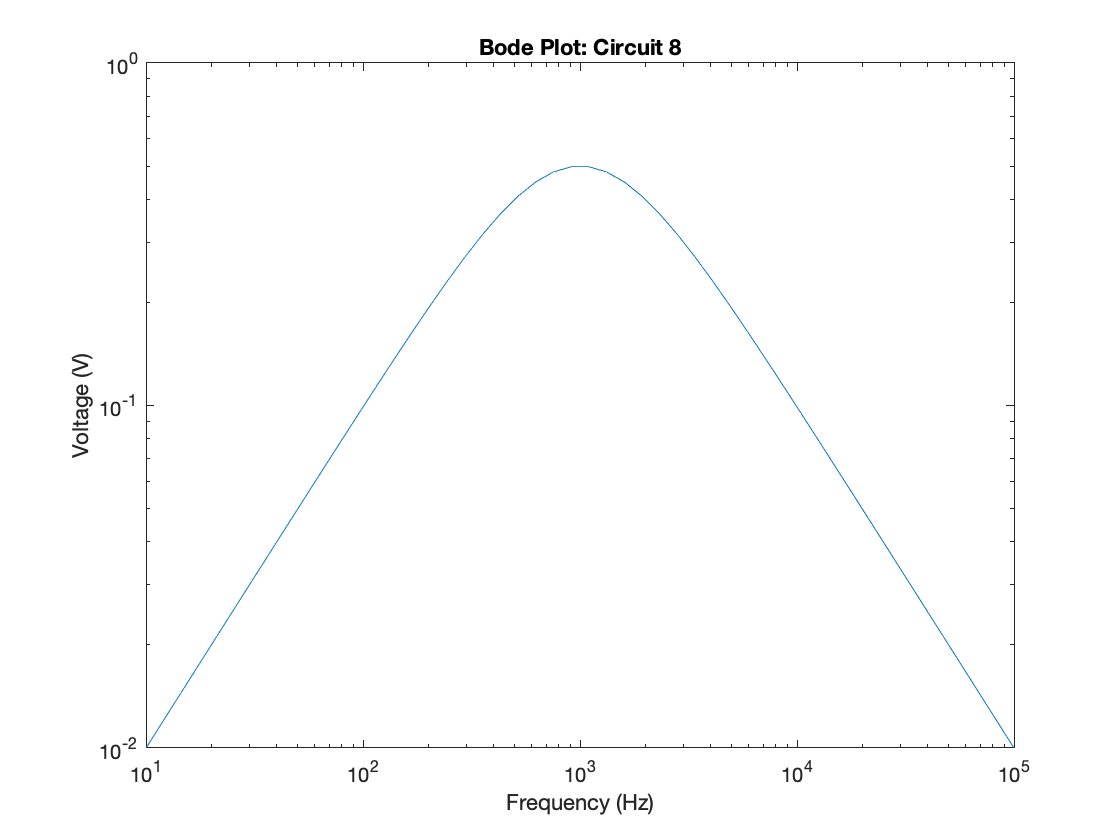

mag = matlabFunction(norm(subs(V_8, [R1, R2, C1, C2], [1000, 10000, 10^-6, 10^-7])));
freq_range = logspace(1, 5);
loglog(freq_range, mag(freq_range));
title("Bode Plot: Circuit 8");
xlabel("Frequency (Hz)");
ylabel("Voltage (V)");